clear
addpath 'C:\Users\Michael\Documents\Facultate\AN-IV\SCR\SCARA'
load("trajectories.mat");
modelName = 'CONTROL_HOLIST_ID';

load_system(modelName);
out = sim(modelName);

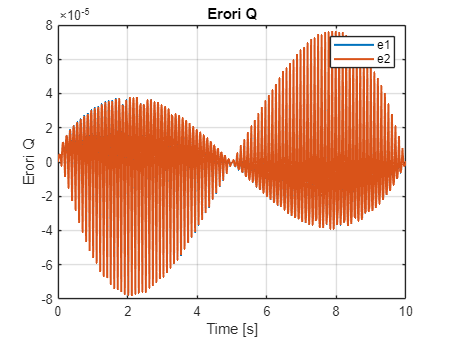

errors_Q  = out.errors_Q;
errors_dQ  = out.errors_dQ;
voltage   = out.voltage;

erori_Q_data = squeeze(errors_Q.Data);
erori_dQ_data = squeeze(errors_dQ.Data);
comanda_data  = squeeze(voltage.Data);

figure
plot(errors_Q.Time, erori_Q_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Errors Q')
title('Errors Q')
legend('e1', 'e2')

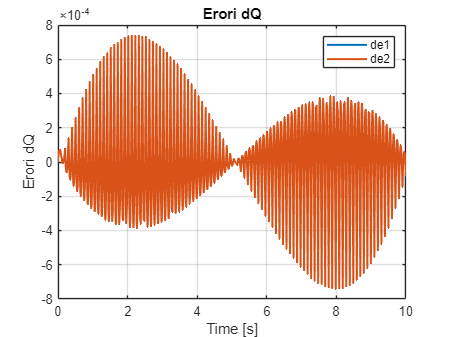


figure
plot(errors_dQ.Time, erori_dQ_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Errors dQ')
title('Errors dQ')
legend('de1', 'de2')

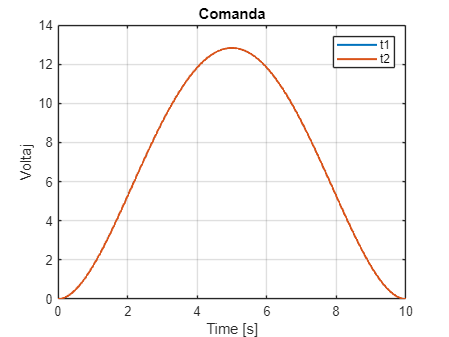


figure
plot(voltage.Time, comanda_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Voltaj')
title('Voltage')
legend('t1', 't2')